# Color Beats Challenge - See Your Voice

In the Bright Beats Challenge, you turned **light into sound**. You built a micro:bit device that "read" a picture and sang it to you. This activity runs the challenge **backwards**: you will turn **sound into light**.

Here is the big idea. Every sound is a wiggle in the air. Fast wiggles sound high. Slow wiggles sound low. Light works the same way: fast light waves look violet, slow light waves look red. So we can give every sound the color of the light that wiggles at the same speed. Your voice becomes a painting.

By the end, you will have recorded your own voice and turned it into a picture you can print and hang up.

*Note:* this activity records from a real microphone. You can run it in **MATLAB Mobile** on a phone or tablet, or run it on a computer and choose a computer microphone.

By default, the lines of code underlying these activities have been hidden. However, if you'd like to peek under the hood and understand how each of these activities have been enabled by programming, you can toggle between different views using these buttons on the right hand toolstrip:

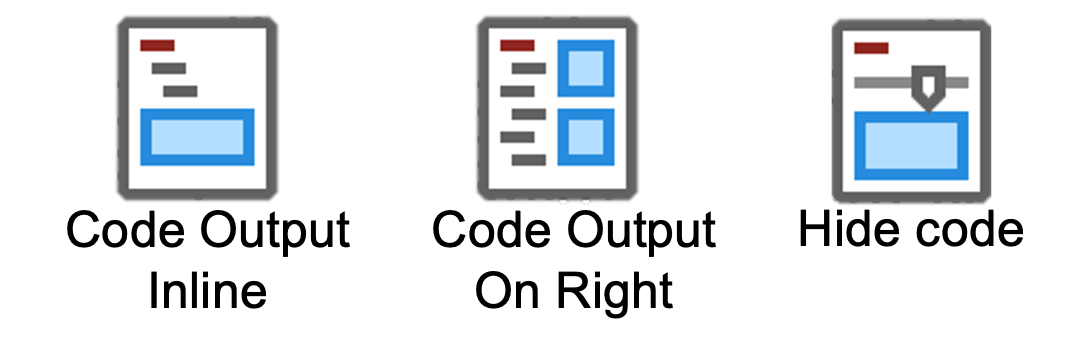

## Get Started: wake up the microphone

Before MATLAB can hear you, choose where the microphone is and give MATLAB permission to use it.

If you are using MATLAB Mobile, follow the instructions below first:

- In MATLAB Mobile, tap the **menu**, then **Sensors**, then **More**.

- Turn on **Sensor Access**.

- Turn on **Microphone**.

- Come back here and run this section.

If you are using a computer, set `microphoneSource` to `"Computer"`. MATLAB will show a list of microphones attached to your computer.

The code below connects this script to your microphone. If you use MATLAB Mobile and get an error, go back and check the three switches above.

 
microphoneSource = "Computer";  % Choose "Mobile device" or "Computer".

switch microphoneSource
    case "Mobile device"
        m = mobiledev;
        if ~m.Connected
            error("Couldn't reach the device. Turn on Sensor Access: menu -> Sensors -> More.")
        end
        m.MicrophoneEnabled = 1;
        disp("Mobile microphone is awake. You're ready to go!")

    case "Computer"
        m = choose_computer_microphone;
        disp("Computer microphone is ready: " + m.Name)

    otherwise
        error("microphoneSource must be ""Mobile device"" or ""Computer"".")
end

## Part 1: Build your color key

Before you paint anything, you need a **decoder ring**: a chart that tells you which pitch makes which color. Low pitches get warm colors, high pitches get cool colors.

Two numbers control the whole key. `minPitch` is the lowest pitch that gets a color, and it comes out **red**. `maxPitch` is the highest pitch that gets a color, and it comes out **violet**. Everything in between gets a rainbow color.

The starting numbers cover about three octaves, which is roughly the range of a singing voice from a low bass up to a high soprano.

minPitch = 130;
maxPitch = 1050;

Now build the rainbow. 

 
build_the_rainbow(minPitch, maxPitch)

**Try it.** Each label shows a musical note and its exact frequency, like C3 and 130.81 Hz. Those are two names for the same thing: the note is what a musician calls it, the frequency is how many times per second the air wiggles.

**Reflect.** Slide `minPitch` up and `maxPitch` down so the key covers a narrow range. What happens to the rainbow? Now stretch them far apart. When would a narrow key be more useful than a wide one?

## Part 2: Record your voice and paint it

Time to make some noise. Type your preferred recording duration, then press the button. You get a countdown, and then MATLAB listens to you for that many seconds. Speak, sing, whistle, or hum.

recordSeconds = 10;
 
recording = record_your_voice(m, recordSeconds);

**Reflect.** That is your voice as a list of numbers. Where the wiggle is tall, you were loud. Where it is flat, you were quiet. Can you find the exact moment you started making noise?

## Part 3: Loud, quiet, clean, and messy

Now we chop your sound into short slices. Each slice becomes one colored stripe in your painting. A slice of sound is called a **frame**, the same way a tiny piece of a picture is called a pixel.

For every frame, MATLAB asks three questions, and each answer becomes one ingredient of the color:

- **How loud is it?** Loud makes the color **bright**, quiet makes it **dark**, and silence makes it **black**.

- **What pitch is it?** This picks the **color** off your key from Part 1.

- **Is it a clean note or messy noise?** A whistle puts all its energy into one pitch, so it comes out **vivid**. A "shhhh" spreads energy over every pitch at once, so it comes out **washed-out white**.

`frameTime` sets how much sound goes into each stripe. `silenceLevel` sets how quiet counts as silence.

frameTime    = 0.05; % how much sound goes into each stripe
silenceLevel = 0.05; % how quiet counts as silence
 
painting = paint_the_sound(recording, minPitch, maxPitch, frameTime, silenceLevel);

**There it is: your voice as a picture.** Read it left to right, like a sentence.

**Try it.** Turn `frameTime` all the way down, then all the way up. Small frames give you thin stripes and lots of detail. Big frames give you wide stripes and a blurry summary. Is there such a thing as too much detail?

**Try it.** Turn `silenceLevel` up until parts of your painting go black. You just told MATLAB "anything quieter than this is nothing." Where should that line be?

**Challenge.** Record again in Part 2, but this time make one long low hum, then one long high whistle. Predict the two colors **before** you look. Were you right?

**Challenge**. Record again in Part 2, but this time try to make a rainbow. Slide your voice from your lowest hum to your highest whistle. Can you get red to violet in one breath?

**Challenge**. Record again in Part 2, but this time paint it black. Can you create a black strip in the **middle** of your recording?

**Challenge**. Record again in Part 2, but this challenge a friend to hit a target color. Someone picks a color. You find the pitch that paints it. Closest match wins!

## Part 4: What did you make?

The painting tells you the story of your sound, but every stripe is hiding a number. This last plot shows the **pitch** behind each color, so you can see exactly which notes your voice hit. Then MATLAB prints a short summary of what you recorded.

 
show_pitch_scatter(painting)
summarize_your_sound(painting)

**Challenge.** Record two very different sounds (like a hum and a whistle) and compare their scatter plots. Do the dots cluster where you expect? What does that tell you about your voice?

## Part 5: A different kind of painting

In Part 3, MATLAB gave each moment **one** color based on the strongest pitch. But most real sounds have several pitches happening at the same time. When you say "ahhh," your voice makes a low pitch **and** a whole stack of higher pitches on top of it. Those extras are called **harmonics**, and they are what makes your voice sound different from a violin, even when you sing the same note.

A **spectrogram** shows all of it at once. Time runs left to right. Pitch runs bottom (low) to top (high). Bright color means loud, dark color means quiet. Think of it as an X-ray of your voice.

`minFreq` and `maxFreq` set the pitch range you want to see. Notice `maxFreq` goes way past singing range, up to 4000 Hz, so you can see harmonics too.

minFreq        = 80; % bottom of the pitch range you want to see
maxFreq        = 4000; % top of the pitch range you want to see
windowTime     = 0.05;  % seconds, the time slice used to make the spectrogram. 
% A smaller windowTime gives better time detail while a bigger window gives better frequency detail.
overlapPercent = 75; % Percent overlap between time slices. 
% If overlapPercent = 0, slices touch but don't overlap. If overlapPercent
% = 50, each new slice starts halfway through the previous one. More
% overlap gives smoother time changes in the spectrogram but requires more
% computation; less overlap is faster but can miss fast changes.

 
show_spectrogram(recording, minFreq, maxFreq, windowTime, overlapPercent)


**Reflect.** Do you see stripes stacked on top of each other? Those are harmonics -- the extra pitches hiding inside every real sound. A whistle is close to a pure note, so it makes **one** stripe. Talking makes a whole ladder of stripes.

**Reflect.** Turn `windowTime` up and down. Small windows show sharp changes in time but blurry pitch. Big windows show sharp pitch but blurry time. You cannot have both -- this is a real puzzle scientists deal with when they study sound.

**Challenge**. Holding a steady pitch (by singing one note) appears as a horizontal line in the spectrogram. Making short, sharp sounds (like claps, short whistles, or pops appears as a vertical line. Gliding your voice up and down smoothly can create diagonal streaks. Can you **make the following shapes** by recording different sounds? Hint: you may need a friend for some of these!

- Rectangle

- Triangle

- House

- Staircase

## Summary

Nice work. Here is what you did:

- Sound and light are both waves, so a pitch can be matched to a color by how fast it wiggles.

- A microphone turns a sound into a long list of numbers, and MATLAB can measure that list.

- Chopping a signal into frames lets you see how it changes over time instead of all at once.

- One color carries three separate measurements at the same time: pitch, loudness, and purity.

- In the Bright Beats Challenge you turned light into sound. Here you turned sound into light. The same idea runs both directions.

## Future Learning

- New to MATLAB? Try [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)

- Learn more about sound and audio signals: [Bytes and Beats](https://www.mathworks.com/academia/courseware/bytes-and-beats.html)

- Learn more about images: [Pixels to Pictures](https://www.mathworks.com/academia/courseware/pixels-to-pictures.html)

- Learn more about signals: [Signal Processing Onramp](https://matlabacademy.mathworks.com/details/signal-processing-onramp/signalprocessing)

## Optional

If you are using a computer with a built-in microphone, you can run these activities using the Color Beats App rather than this MATLAB script. To run the app, use the button below.

run("ColorBeatsApp.m");
 

## Helper functions (leave these alone)

function build_the_rainbow(minPitch, maxPitch)
% We use log2 because your ears hear pitch in octaves:
% doubling a frequency always sounds like "one step up," whether you start low or high.
% So the colors should step up the same way.
keyFreq = logspace(log10(minPitch), log10(maxPitch), 400);
keyHue  = 0.8 * (log2(keyFreq) - log2(minPitch)) / (log2(maxPitch) - log2(minPitch));
hsvKey = zeros(1, numel(keyFreq), 3);
hsvKey(1,:,1) = keyHue;
hsvKey(1,:,2) = 1;
hsvKey(1,:,3) = 1;
image([1 numel(keyFreq)], [0 1], repmat(hsv2rgb(hsvKey), 60, 1, 1))
set(gca, "YTick", [])
numLabels   = 7;
targetFreqs = logspace(log10(minPitch), log10(maxPitch), numLabels);
noteFreqs   = zeros(1, numLabels);
notes       = strings(1, numLabels);
for k = 1:numLabels
    [notes(k), noteFreqs(k)] = freq2note(targetFreqs(k));
end
xTicks = interp1(keyFreq, 1:numel(keyFreq), noteFreqs, "linear", "extrap");
xTicks = min(max(xTicks, 1), numel(keyFreq));   % keep end labels on the chart
set(gca, "XTick", xTicks, "XTickLabel", compose("%s (%.2f Hz)", notes', noteFreqs'))
title("Your Color Key: low pitch = red, high pitch = violet")
xlabel("Pitch (musical note)")
end

function mic = choose_computer_microphone
% Let desktop MATLAB users choose an input device from the computer.
    info = audiodevinfo;
    inputDevices = info.input;
    if isempty(inputDevices)
        error("MATLAB did not find any computer microphones. Check your system audio settings.")
    end

    deviceNames = string({inputDevices.Name});
    if usejava("desktop")
        [whichDevice, ok] = listdlg("PromptString", "Choose a computer microphone:", ...
            "SelectionMode", "single", "ListString", cellstr(deviceNames), ...
            "Name", "Choose Microphone", "ListSize", [360 180]);
        if ~ok
            error("No microphone was selected.")
        end
    else
        disp("Available computer microphones:")
        for k = 1:numel(deviceNames)
            fprintf("%d: %s\n", k, deviceNames(k))
        end
        whichDevice = input("Type the number of the microphone to use: ");
        if isempty(whichDevice) || whichDevice < 1 || whichDevice > numel(deviceNames)
            error("Choose a number from 1 to %d.", numel(deviceNames))
        end
    end

    mic.Type = "Computer";
    mic.Name = deviceNames(whichDevice);
    mic.DeviceID = inputDevices(whichDevice).ID;
    mic.SampleRate = 44100;
end

function recording = record_your_voice(m, recordSeconds)
% Countdown, record from the mic, plot the raw waveform, and return a
% struct with the audio data for later steps.
    disp("Get ready to make a sound!")
    for count = 3:-1:1
        disp("   " + count + "...")
        pause(1)
    end
    disp("GO! Speak, sing, whistle, or hum!")

    if isstruct(m) && isfield(m, "Type") && m.Type == "Computer"
        recorder = audiorecorder(m.SampleRate, 16, 1, m.DeviceID);
        recordblocking(recorder, recordSeconds);
        fs = m.SampleRate;
        audioData = getaudiodata(recorder);
    else
        fprintf("\n")
        m.Logging = 0;
        audioData = readAudio(m);
        fs = m.Microphone.SampleRate;
    end
    disp("Done recording.")

    if isempty(audioData)
        error("No audio came through. Check that the microphone is on, then try again.")
    end
    y = mean(audioData, 2);
    if max(abs(y)) == 0
        error("This recording is completely silent. Try again, a bit louder.")
    end
    y = y / max(abs(y));

    recording.y        = y;
    recording.fs       = fs;
    recording.duration = numel(y) / recording.fs;

    plot((0:numel(y)-1)/recording.fs, y, "k")
    title("Your sound as a wiggle")
    xlabel("Time (s)")
    ylabel("Wiggle size")
    axis tight
    grid on
end

function painting = paint_the_sound(recording, minPitch, maxPitch, frameTime, silenceLevel)
% Slice the sound into frames, measure loudness / pitch / purity of each,
% map those to HSV colors, draw the painting, and return everything Part 4 needs.
    y  = recording.y;
    fs = recording.fs;

    % Chop into frames.
    N         = round(frameTime * fs);
    numFrames = floor(numel(y) / N);
    frames    = reshape(y(1:numFrames*N), N, numFrames);
    frameTimes = (0:numFrames-1) * frameTime;

    % Loudness of each frame.
    loudness = sqrt(mean(frames.^2, 1));

    % Pitch and purity via FFT.
    window   = 0.5 - 0.5*cos(2*pi*(0:N-1)'/(N-1));
    spectrum = abs(fft(frames .* window));
    spectrum = spectrum(1:floor(N/2), :);
    freqAxis = (0:floor(N/2)-1)' * (fs/N);
    inRange  = freqAxis >= minPitch & freqAxis <= maxPitch;
    band     = spectrum(inRange, :);
    bandFreq = freqAxis(inRange);
    [peakStrength, whichRow] = max(band, [], 1);
    pitch  = reshape(bandFreq(whichRow), 1, []);
    purity = peakStrength ./ (sum(band, 1) + eps);

    % Map to HSV.
    hue        = 0.8 * clamp01(log2(pitch) - log2(minPitch), 0, log2(maxPitch) - log2(minPitch));
    saturation = clamp01(purity, 0.02, 0.15);
    sorted     = sort(loudness);
    loudRef    = sorted(max(1, ceil(0.95*numFrames)));
    brightness = clamp01(loudness / loudRef, 0, 1) .^ 0.4;

    % Silence gets painted black.
    isQuiet = loudness < silenceLevel * loudRef;
    brightness(isQuiet) = 0;
    saturation(isQuiet) = 0;
    pitch(isQuiet)      = NaN;

    % HSV -> RGB.
    hsvStrip = zeros(1, numFrames, 3);
    hsvStrip(1,:,1) = hue;
    hsvStrip(1,:,2) = saturation;
    hsvStrip(1,:,3) = brightness;
    rgbStrip = hsv2rgb(hsvStrip);

    % Draw the painting.
    image([0 recording.duration], [0 1], repmat(rgbStrip, 60, 1, 1))
    title("Your sound as a painting")
    xlabel("Time (s)")
    set(gca, "YTick", [])

    % Package everything Part 4 needs.
    painting.frameTimes = frameTimes;
    painting.pitch      = pitch;
    painting.hue        = hue;
    painting.rgbStrip   = rgbStrip;
    painting.isQuiet    = isQuiet;
    painting.duration   = recording.duration;
    painting.minPitch   = minPitch;
    painting.maxPitch   = maxPitch;
end

function show_pitch_scatter(painting)
% Show a scatter of pitch vs. time, colored to match the painting.
    figure
    scatter(painting.frameTimes, painting.pitch, 40, squeeze(painting.rgbStrip), ...
        "filled", "MarkerEdgeColor", [0.6 0.6 0.6])
    title("The pitch behind each color")
    xlabel("Time (s)")
    ylabel("Pitch (Hz)")
    xlim([0 painting.duration])
    ylim([painting.minPitch painting.maxPitch])
    grid on
end

function summarize_your_sound(painting)
% Print average pitch, dominant color, and how much time was silence.
    heard = ~painting.isQuiet;
    if any(heard)
        fprintf("Your average pitch was %.0f Hz.\n", mean(painting.pitch(heard), "omitnan"))
        fprintf("Your sound is mostly %s.\n", colorName(mean(painting.hue(heard))))
        fprintf("You were silent %.0f%% of the time.\n", 100*mean(painting.isQuiet))
    else
        disp("Everything was below the silence level. Record a little louder!")
    end
end

function show_spectrogram(recording, minFreq, maxFreq, windowTime, overlapPercent)
% Compute a spectrogram of the recording and display it.
% A spectrogram is a picture of how loud each pitch is at every moment in time.
% Time runs left to right. Pitch runs bottom (low) to top (high).
% Bright color = loud, dark color = quiet.
    [S, F, T] = compute_spectrogram(recording.y, recording.fs, windowTime, overlapPercent);

    % Convert to log-brightness so quiet details are visible.
    brightness = 20*log10(abs(S) + eps);
    top = max(brightness(:));
    brightness = max(brightness, top - 60);

    imagesc(T, F, brightness)
    axis xy
    ylim([minFreq maxFreq])
    colormap(turbo)
    colorbar
    if top - 60 < top
        clim([top - 60, top])
    end
    title("Your sound as a spectrogram")
    xlabel("Time (seconds)")
    ylabel("Pitch (Hz)")
end

function [S, F, T] = compute_spectrogram(y, fs, windowTime, overlapPercent)
% Use MATLAB's spectrogram function if it is available. Otherwise fall
% back to a base-MATLAB framed FFT so this works even without the
% Signal Processing Toolbox.
    y = y(:);
    nWindow = max(16, round(windowTime * fs));
    nWindow = min(nWindow, numel(y));
    nOverlap = min(max(round(nWindow * overlapPercent / 100), 0), nWindow - 1);
    window = 0.5 - 0.5*cos(2*pi*(0:nWindow-1)'/(nWindow-1));

    if exist("spectrogram", "file") == 2 || exist("spectrogram", "builtin") == 5
        try
            [S, F, T] = spectrogram(y, window, nOverlap, nWindow, fs);
            return
        catch
        end
    end

    % Fallback: framed FFT by hand.
    step = max(1, nWindow - nOverlap);
    starts = 1:step:(numel(y) - nWindow + 1);
    if isempty(starts)
        starts = 1;
        y = [y; zeros(nWindow - numel(y), 1)];
    end
    nFreq = floor(nWindow/2) + 1;
    S = zeros(nFreq, numel(starts));
    for k = 1:numel(starts)
        frame = y(starts(k):starts(k)+nWindow-1) .* window;
        X = fft(frame, nWindow);
        S(:, k) = X(1:nFreq);
    end
    F = (0:nFreq-1)' * (fs/nWindow);
    T = (starts - 1 + nWindow/2) / fs;
end

function [name, snappedFreq] = freq2note(f)
% Find the closest piano note to a frequency, tuned so A4 = 440 Hz.
    noteNames   = ["C","C#","D","D#","E","F","F#","G","G#","A","A#","B"];
    midiNumber  = round(69 + 12*log2(f/440));
    snappedFreq = 440 * 2^((midiNumber-69)/12);
    octave      = floor(midiNumber/12) - 1;
    name        = sprintf("%s%d", noteNames(mod(midiNumber,12)+1), octave);
end

function out = clamp01(x, lo, hi)
% Squash x into the range 0 to 1, based on the low and high limits given.
    out = (x - lo) ./ (hi - lo);
    out = min(max(out, 0), 1);
end

function name = colorName(h)
% Give a plain-English color name to a hue value between 0 and 0.8.
    names = ["red","orange","yellow","green","teal","cyan","blue","violet"];
    idx   = min(8, max(1, floor(h/0.8 * 8) + 1));
    name  = names(idx);
end